# Evaluation script for the effect of introducing refractive index distribution

For the sake of simplification, this script only deals with 1-D sequence as a refractive index distribution.

Requirements:

- Signal Processing Toolbox

- Image Processing Toolbox

- Wavelet Toolbox

Reference:

-  Ruiki Kobayashi, Genki Fujii, Yuta Yoshida, Takeru Ota, Fumiaki Nin, Hiroshi Hibino, Samuel Choi, Shunsuke Ono, and Shogo Muramatsu, "**Sparsity-Aware OCT Volumetric Data Restoration Using an Optical Synthesis Model**,"  submitted to* IEEE Trans. on Computational Imaging*, 2022

-  Genki Fujii, Yuta Yoshida, Shogo Muramatsu, Shunsuke Ono, Samuel Choi, Takeru Ota, Fumiaki Nin, and Hiroshi Hibino, “**OCT Volumetric Data Restoration with Latent Distribution of Refractive Index**,” in *Proceedings of International Conference on Image Processing, (ICIP)*, pp. 764–768, Sept. 2019.

Copyright © 2022 Ruiki KOBAYASHI and Shogo MURAMATSU

## Configuration

rng(0) % Initialize random generator
nSamples = 256; % Number of samples
sigmaw = 0.05; % Standard deviation of AWGN
ri_ub = 1.5; % Upper bound of refractive index
ri_lb = 1.0; % Lower bound of refracitve index

% # of tree level
nLevels = 3; 

% Regularization parameters for proposed method
eta_prop_pds = 5.41e-2;
lambda_prop_pds = 2.51e-3;
eta_prop_admm = 5.41e-2;
lambda_prop_admm = 3.98e-3;

% # of iterations
nIters = 1000;

% for PDS
nIters_pds = nIters; 

%for ADMM
rho_admm = 0.02; 
nIters_admm = nIters; 

% Regularization parameters for refernece method (1D TV)
eta_1dtv = 1.94e-1;
nIters_1dtv = nIters;

% MSE
mymse = @(x,y) mean((x(:)-y(:)).^2);

## Measurement process

   
$$p[m_\mathrm{z}]=\alpha_{\mathrm{p}} \exp \left(-\frac{m_{\mathrm{z}}^{2}}{2 \sigma_{\mathrm{z}}^{2}}\right) \cos \left(\omega_{\mathrm{p}} m_{\mathrm{z}}\right) \mathrm{sinc}\left(b_\mathrm{p} m_{\mathrm{z}}\right), m_\mathrm{z}\in\mathbb{Z}$$


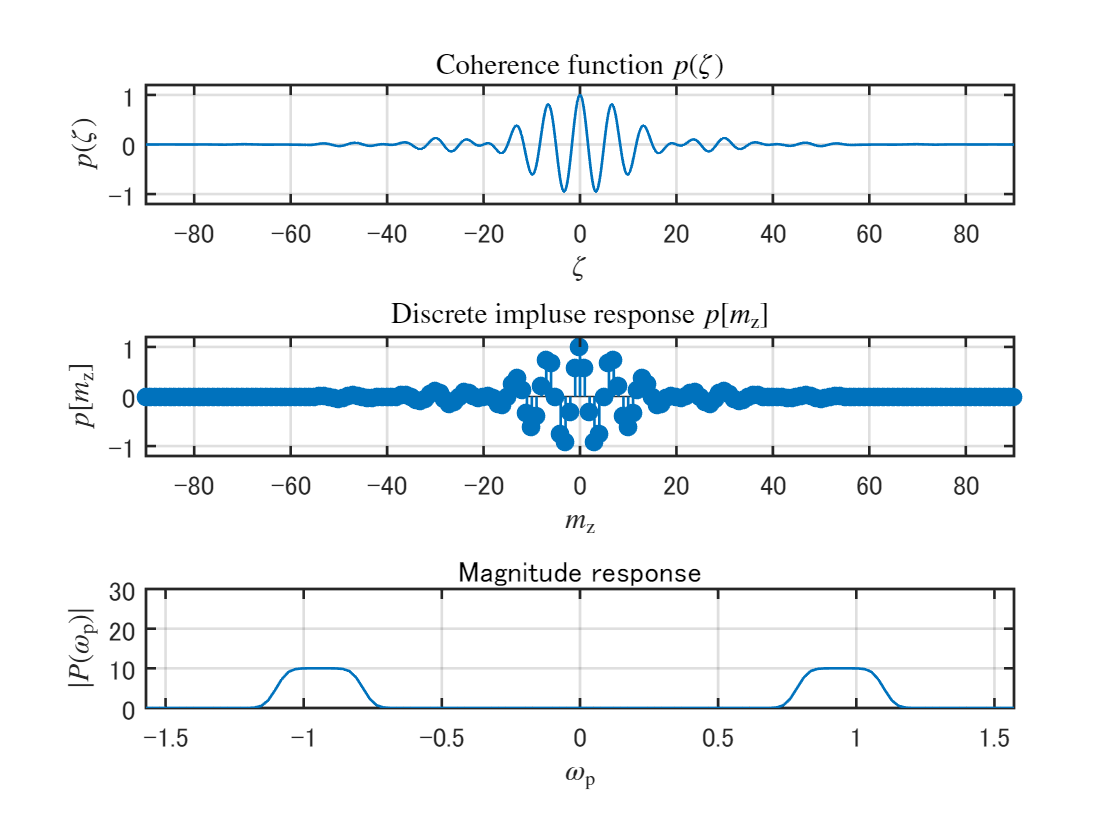

% Parameters
alpha_p = 1.0; % Amplitude
omega_p = 0.3*pi; % Frequency of fluctuation
sigma_z = 30; % Standard deviation of Gaussian function
b_p = 0.05; % Broadening parameter

% Impluse response of measurement process
p = @(m) alpha_p.*exp(-m.^2/(2*sigma_z.^2)).*cos(omega_p*m).*sinc(b_p*m);
% Impulse response of P
hlen = round(3*sigma_z); 
zsmpl = -hlen:hlen;
irp = p(zsmpl); % impluse response of p

% Function shape
hfig = figure;
subplot(3,1,1)
fplot(p,[-hlen hlen])
axis([-hlen hlen -1.2*alpha_p 1.2*alpha_p])
xlabel("$\zeta$","Interpreter","latex")
ylabel("$p(\zeta)$","Interpreter","latex")
title("Coherence function $p(\zeta)$","Interpreter","latex")
subplot(3,1,2)
stem(-hlen:hlen,irp,'fill')
axis([-hlen hlen -1.2*alpha_p 1.2*alpha_p])
xlabel("$m_\mathrm{z}$","Interpreter","latex")
ylabel("$p[m_\mathrm{z}]$","Interpreter","latex")
title("Discrete impluse response $p[m_\mathrm{z}]$","Interpreter","latex")
subplot(3,1,3)
wz = linspace(-pi,pi-(2*pi)/nSamples,nSamples);
arp = fftshift(abs(fft(irp,nSamples)));
plot(wz,arp)
xlabel("$\omega_\mathrm{p}$","Interpreter","latex")
ylabel("$|P(\omega_\mathrm{p})|$","Interpreter","latex")
title('Magnitude response')
axis([-pi/2 pi/2 0 sigma_z*alpha_p])
%
viewhandle_(hfig);


% Measurement process
measureproc = @(x) circshift(cconv(irp,x,nSamples),-floor(length(irp)/2));
measureadjp = @(x) circshift(cconv(irp(end:-1:1),x,nSamples),mod(length(irp)-1,2)-floor(length(irp)/2)); 
% Check if <Px,y> = <x,P.'y> (is adjoint?)
isinadjrel(measureproc,measureadjp,nSamples)

## Generation of refractive index distribution

Generation of a refractive index distribution for simulation

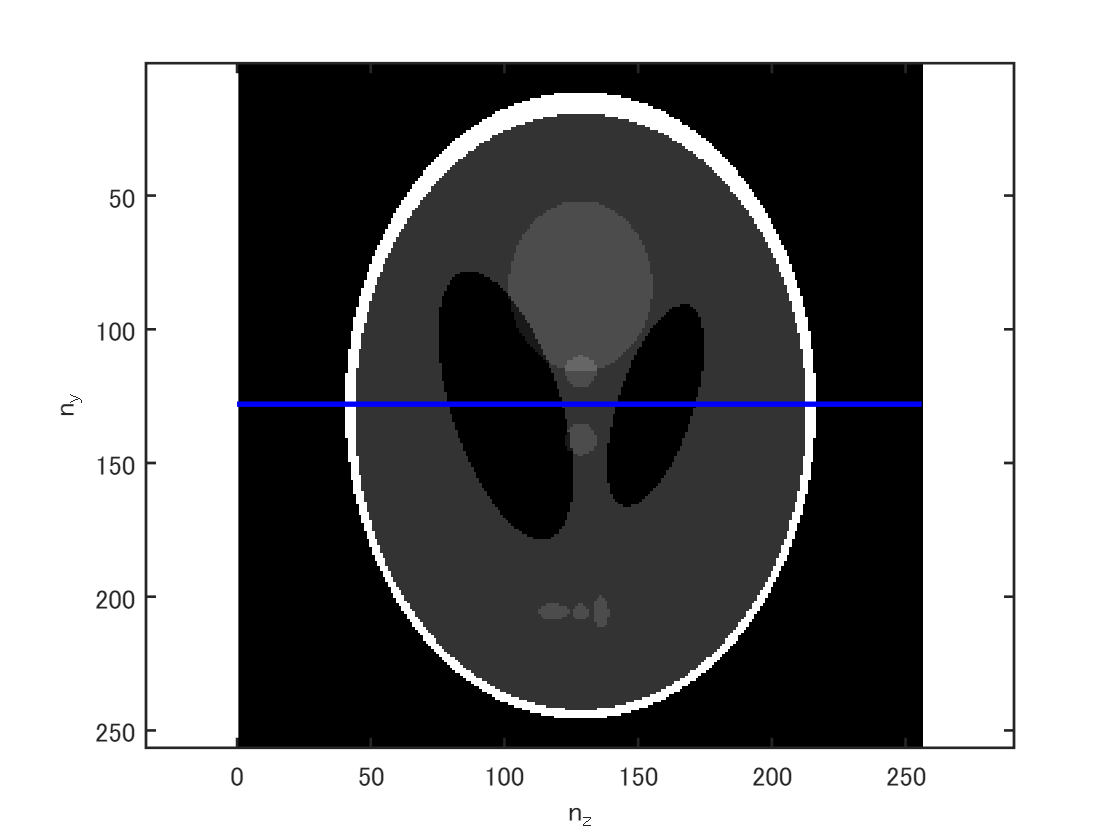

u2d = phantom('Modified Shepp-Logan',nSamples);
minu2d = min(u2d(:));
maxu2d = max(u2d(:));
u2d = (ri_ub-ri_lb)*(u2d-minu2d)/(maxu2d-minu2d)+ri_lb; % Normalize to [a,b]
posy = 128;

hfig = figure;
imagesc(u2d),colormap(gray),axis equal
line([0,256],posy*[1 1],'Color','blue','LineWidth',2)
xlabel('n_z')
ylabel('n_y')
%
axis_ = hfig.Children;
axis_.LineWidth = 1;
axis_.FontSize = 10;

Extraction of 1-D sequence

u = u2d(posy,:);

## Reflection model

    
$$\phi(\mathbf{u})=\mathrm{abs}\left(\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}\right) \odot\left(-\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}\right) \oslash\left(\mathbf{A}_{\mathrm{z}} \mathbf{u}\right)^{\circ 2}$$


where $\mathbf{u}\in[0,\infty)^N$, $\mathbf{\Delta}_z\in\mathbb{R}^{N\times N}$, $\mathbf{A}_z\in\mathbb{R}^{N\times N}$.

From refractive index distribution to reflectance one

    
$$\mathbf{r}=\phi(\mathbf{u})$$


where $\phi: [0,\infty)^N\rightarrow (-1,1)^N$.

r = phi1d(u,'reflection');

Graph plot

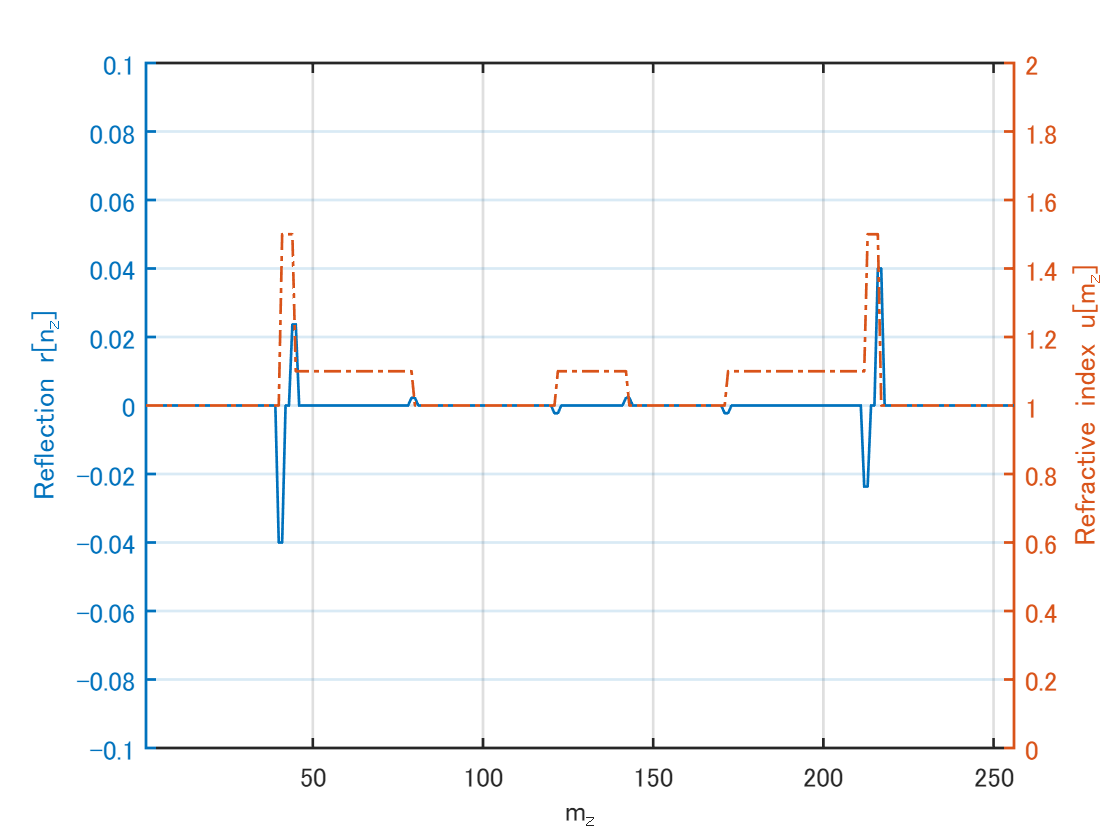

hfig = figure;
yyaxis right
plot(u,'-.','LineWidth',1)
ylabel('Refractive index u[m_z]')
xlabel('m_z')
axis([1 nSamples 0 2])
yyaxis left
plot(r,'LineWidth',1)
ylabel('Reflection r[n_z]')
axis([1 nSamples -0.1 0.1])
grid on
%
axis_ = hfig.Children;
axis_.LineWidth = 1;
axis_.FontSize = 10;

## Observation

    
$$\mathbf{v}=\mathbf{P} \phi(\mathbf{u})+\mathbf{w},\ \text { s.t. }\ \mathbf{u} \in[a, b]^{N}, a, b \in[0, \infty)$$


where the domain of $\phi$ is defined as $[a,b]^N$, i.e., possible values for the refractive index.

% AWGN 
w = sigmaw*randn(size(r));

% Observation
v = measureproc(r) + w;

Graph plot

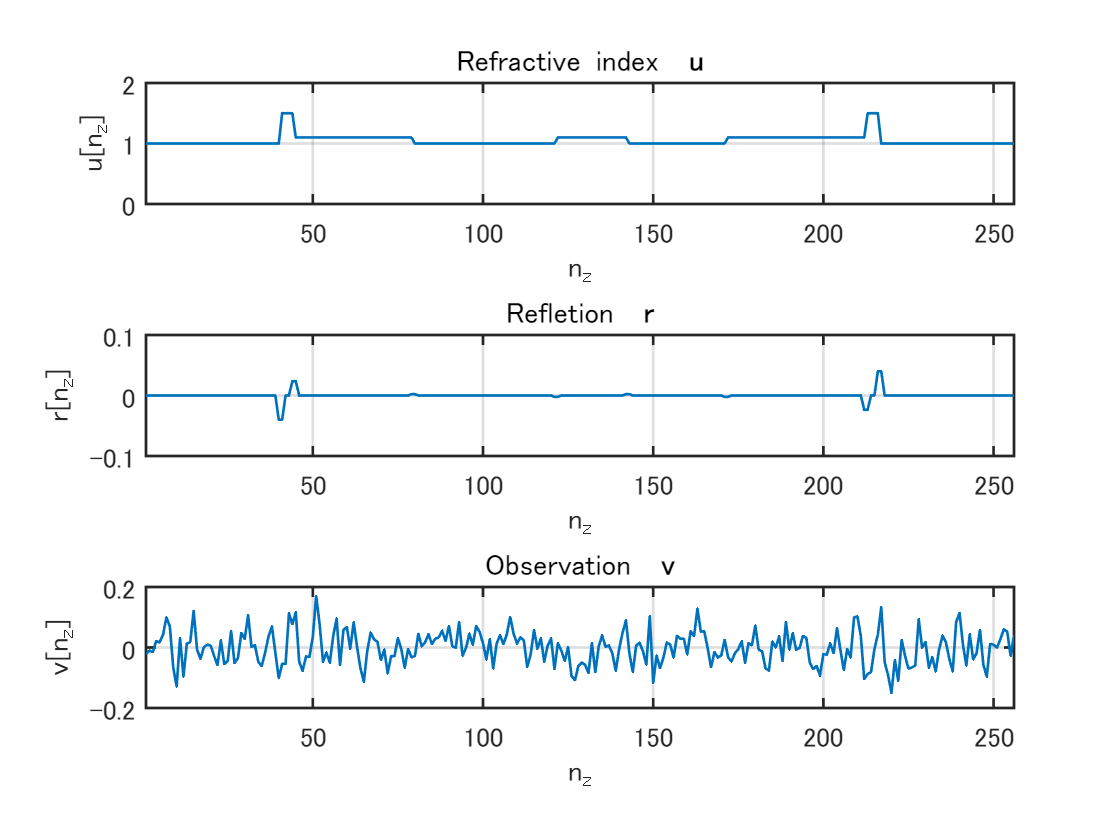

hfig = figure;
subplot(3,1,1)
plot(u)
title('Refractive index {\bf u}')
xlabel('n_z')
ylabel('u[n_z]')
axis([1 nSamples 0 2])
subplot(3,1,2)
plot(r)
title('Refletion {\bf r}')
xlabel('n_z')
ylabel('r[n_z]')
axis([1 nSamples -0.1 0.1])
subplot(3,1,3)
plot(v)
title('Observation {\bf v}')
xlabel('n_z')
ylabel('v[n_z]')
axis([1 nSamples -0.2 0.2])
hold off
%
viewhandle_(hfig)

## Proposed restoration model

    
$$\hat{\mathbf{s}}=\arg \min _{\mathbf{s} \in \mathbb{R}^{L}} \frac{1}{2}\|\mathbf{P} \phi_1(\mathbf{D s})-\mathbf{v}\|_{2}^{2}+\lambda\|\mathbf{s}\|_{1}+\eta\left\|\Delta_{z} \mathbf{D} \mathbf{s}\right\|_{1},\ \text { s.t. }\ \mathbf{u}=\mathbf{D} \mathbf{s} \in[a, b]^{N}$$


    
$$\hat{\mathbf{r}}=\phi_1(\mathbf{D}\hat{\mathbf{s}})=\mathbf{\Phi}_1\mathbf{D}\hat{\mathbf{s}}$$


where $\mathbf{D}\in\mathbb{R}^{N\times L}$ is a synthesis dictionary and $\phi_1: [a,b]^N\rightarrow (-1,1)^N$ is a linear approximation of $\phi$ as

    $\phi_1(\mathbf{u})= \mathbf{\Phi}_1\mathbf{u}=-\beta_1(a,b)\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}$,

    $\beta_1(a,b)=\frac{2|b-a|}{(b+a)^2}$ ,   

    
$$\mathbf{\Phi}_1\in\mathbb{R}^{N\times N}$$


The Jacobian is given by 

    
$$\frac{\partial\phi_1}{\partial\mathbf{u}}=\mathbf{\Phi}_1= \beta_1(a,b)\mathbf{\Delta}_{\mathrm{z}}^T$$


## Parseval tight dictionary

- $\mathbf{D}$: Parseval tight convolutional synthesizer

- $\mathbf{D}^T$: Adjoint of $\mathbf{D}$, convolutional analyzer

Parseval tight dictionary $\mathbf{D}$ satisifies

    $\mathbf{D}\mathbf{D}^T=\mathbf{I}$.

The undecimated Haar transform is one of such dictionaries.

Generation of the undecimated Haar dictionary, where functions SWT and ISWT are used and the coefficients are scaled so that the dictionary becomes a tight frame.

t_ = randn(1,nSamples);
y_ = udhaardec(t_,nLevels); % Analyzer D.'
z_ = udhaarrec(y_,nLevels); % Synthesizer D
% Check if D is Parseval tight
assert(norm(t_)-norm(y_)<1e-9 & norm(t_-z_)<1e-9,'Parseval tight property does not met.')
x1 = randn(1,nSamples);
y1 = udhaardec(x1,nLevels);
y2 = randn(1,nSamples*(nLevels+1));
x2 = udhaarrec(y2,nLevels);
err = abs(x1(:).'*x2(:)-y1(:).'*y2(:));
assert(err<1e-9,'Adjoint relation is not met. (abs err: %f)',err)
analyzer = @(x) udhaardec(x,nLevels);
synthesizer = @(y) udhaarrec(y,nLevels);

## PDS approach

PDS realization for solving the proposed restoration model is as follows:

Initalization    $\mathbf{s}^{(0)}\in\mathbb{R}^L$, $\mathbf{y}_1^{(0)}\in\mathbb{R}^N$, $\mathbf{y}_2^{(0)}\in\mathbb{R}^N$,  $\mathbf{u}^{(0)}=\mathbf{D}\mathbf{s}^{(0)}$ ,  $n \leftarrow 0$                     

- 
$$\mathbf{t}\gets\mathbf{D}^T(\nabla \mathcal{F}(\mathbf{u}^{(n)})+\mathbf{\Delta}_\mathrm{z}^T\mathbf{y}_1^{(n)}+\mathbf{y}_2^{(n)})$$


- 
$$\mathbf{s}^{(n+1)} =\mathfrak{G}_{\lambda\|\cdot\|_1}(\mathbf{s}^{(n)}-\gamma_1\mathbf{t},\gamma_1^{\frac{1}{2}})$$


- 
$$\mathbf{u}^{(n+1)} = \mathbf{D}\mathbf{s}^{(n+1)}$$


- 
$$\mathbf{q} \gets 2\mathbf{u}^{(n+1)}-\mathbf{u}^{(n)}$$


- 
$$\mathbf{y}_1^{(n)} \gets \mathbf{y}_1^{(n)} +\gamma_2\mathbf{\Delta}_\mathrm{z}\mathbf{q}$$


- 
$$\mathbf{y}_2^{(n)} \gets \mathbf{y}_2^{(n)} +\gamma_2\mathbf{q}$$


- 
$$\mathbf{y}_1^{(n+1)} =  \mathbf{y}_1^{(n)} -\gamma_2\mathfrak{G}_{\eta\|\cdot\|_1}(\gamma_2^{-1}\mathbf{y}_1^{(n)},\gamma_2^{-\frac{1}{2}})$$


- 
$$\mathbf{y}_2^{(n+1)} = \mathbf{y}_2^{(n)} -\gamma_2P_{[a,b]^N}(\gamma_2^{-1}\mathbf{y}_2^{(n)})$$


- 
$$n\leftarrow n+1$$


where

    
$$\nabla\mathcal{F}(\mathbf{x})=\beta_1(a,b)\mathbf{\Delta}_\mathrm{z}\mathbf{P}^T(\beta_1(a,b)\mathbf{P}\mathbf{\Delta}_\mathrm{z}^T\mathbf{x}-\mathbf{v})$$


    
$$\mathfrak{G}_{\lambda\|\cdot\|_1}(\mathbf{x},\sqrt{\gamma_1})=\mathcal{T}(\mathbf{x},\lambda\gamma_1)=\mathrm{sign}(\mathbf{x}) \odot\max\left\{\mathrm{abs}(\mathbf{x})-\lambda\gamma_1\mathbf{1},\mathbf{0}\right\}$$


    
$$\gamma_2\mathfrak{G}_{\eta\|\cdot\|_1}(\gamma_2^{-1}\mathbf{y},\sqrt{\gamma_2})=\gamma_2\mathcal{T}(\gamma_2^{-1}\mathbf{y},\eta\gamma_2)=\mathrm{sign}(\mathbf{y}) \odot\max\left\{\mathrm{abs}(\mathbf{y})-\eta\mathbf{1},\mathbf{0}\right\}=\mathcal{T}(\mathbf{y},\eta)$$


where $\mathcal{T}(\cdot,\tau)$ is the soft-thresholding function with threshold $\tau$.

### Difference operators

For simplicity, we set

- $\mathbf{\Delta}_z$: Convolutional operator with $(z_z-z_z^{-1})/2$

- $\mathbf{A}_z$: Convolutional operator with $(z_z+z_z^{-1})/2$

% Impluse response of the first-order difference filter
dltz = [1 0 -1]/2;
addz = [1 0  1]/2;
% Convolutional operations
dltzproc = @(x) circshift(cconv(dltz,x,nSamples),-floor(length(dltz)/2));
dltzadjp = @(x) -dltzproc(x);
addzproc = @(x) circshift(cconv(addz,x,nSamples),-floor(length(addz)/2)); 
addzadjp = @(x) addzproc(x);
% Check if <Px,y> = <x,P.'y> (is adjoint?)
isinadjrel(dltzproc,dltzadjp,nSamples)
isinadjrel(addzproc,addzadjp,nSamples)

Initialization

beta1_ = beta1(ri_lb,ri_ub); % β1(a,b)
u0 =  beta1_*dltzproc(measureadjp(v)); % Δz.'P.'v
%u0 = (ri_ub-ri_lb)*rand(size(v))+ri_lb; % Uniform distribution [a,b]
sp = analyzer(u0); % s0 = D.'u0
y1p = zeros('like',v); % y10 = 0;
y2p = zeros('like',v); % y20 = 0;
up = u0;

Settings for stepsize $\gamma_2$

    $\mu=(\beta_1(a,b)\sigma_\mathrm{max}(\mathbf{P\mathbf{\Delta}_\mathrm{z}\mathbf{D}))^2$.

Especially, for a Parseval tight $\mathbf{D}$, 

    $\mu=(\beta_1(a,b)\sigma_\mathrm{max}(\mathbf{P\mathbf{\Delta}_\mathrm{z}))^2$.

irpd = cconv(irp,dltz,nSamples); % Impulse response of convolutional operator PΔz
mu_pds = beta1_.^2*max(abs(fft(irpd,nSamples)).^2,[],'all'); % (beta1(a,b)*σmax(PΔz))^2
dltzLambdaMax = max(abs(fft(dltz,nSamples)).^2,[],'all'); % λmax(Δz.'*Δz)
tau2_pds = dltzLambdaMax + 1; % (σmax(L))^2 = λmax(Δz.'*Δz) + 1
gamma1_pds = 2/(1.05*mu_pds);
gamma2_pds = 1/(1.05*tau2_pds)*(1/gamma1_pds-mu_pds/2);
assert((1/gamma1_pds - gamma2_pds*tau2_pds) > mu_pds/2,...
    ['Step size condition is violated. γ1 must be less than ' num2str(2/mu_pds)])
strbuf = "";
strbuf = strbuf.append("mu: "+ num2str(mu_pds) + newline);
strbuf = strbuf.append("tau2: " +  num2str(tau2_pds) + newline);
strbuf = strbuf.append("gamma1: " +  num2str(gamma1_pds) + newline);
strbuf = strbuf.append("gamma2: " +  num2str(gamma2_pds) + newline);
disp(strbuf)

mu: 1.8172
tau2: 2
gamma1: 1.0482
gamma2: 0.021633



Graph plot

hfig = figure;
subplot(3,1,1)
plot(u,'-.') % Original refractive index distribution
utitle = title(['Restoration w/ PropPds \^{\bf u}: #itr ' num2str(0)]);
xlabel('n_z')
ylabel('u[n_z]')
axis([1 nSamples 0 2])
hold on
huc = plot(up); % Restored refractive index distribution
hold off
%
subplot(3,1,2)
plot(r,'-.') % Original reflectance distribution
rtitle = title(['Restoration w/ PropPds \^{\bf r}: #itr ' num2str(0)]);
xlabel('n_z')
ylabel('r[n_z]')
axis([1 nSamples -0.1 0.1])
hold on
rp = v;
hrc = plot(rp); % Restored reflectance distribution
hold off
%
subplot(3,1,3)
plot(v) % Observation
title('Observation {\bf v}')
xlabel('n_z')
ylabel('v[n_z]')
axis([1 nSamples -0.2 0.2])
%
viewhandle_(hfig)
drawnow

Primal-dual splitting for proposal

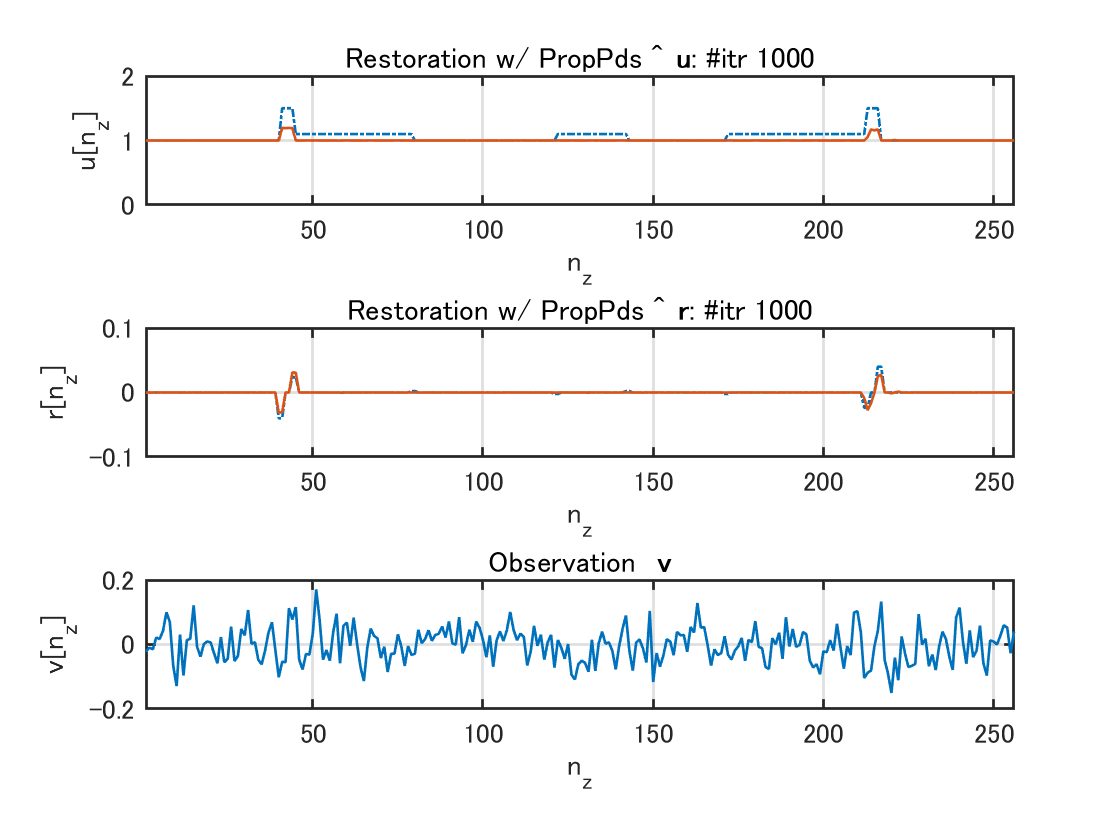

mse_r_proppds = zeros(nIters_pds,1);
proctime_proppds = 0;
for itr=1:nIters_pds
    tic
    % Primal step
    nablaF = beta1_*dltzproc( measureadjp( beta1_*measureproc(dltzadjp(up)) - v ) );
    t_ = analyzer(nablaF + dltzadjp(y1p) + y2p); 
    sc = softthresh( sp - gamma1_pds*t_, lambda_prop_pds*gamma1_pds );
    uc = synthesizer(sc);
    % Dual step
    q_ = 2*uc - up;
    y1p = y1p + gamma2_pds * dltzproc(q_);
    y2p = y2p + gamma2_pds * q_;
    y1c = y1p - softthresh(y1p,eta_prop_pds);
    y2c = y2p - gamma2_pds * metricproj(y2p/gamma2_pds,ri_lb,ri_ub);
    % Update 
    sp = sc;
    y1p = y1c;
    y2p = y2c;
    up = uc;
    % Time measurement
    proctime_proppds = proctime_proppds + toc;

    % Process for monitoring
    rc = phi1d(uc,'linear',[ri_lb ri_ub]);
    hrc.YData = rc;
    rtitle.String = ['Restoration w/ PropPds \^{\bf r}: #itr ' num2str(itr)];
    huc.YData = uc;
    utitle.String = ['Restoration w/ PropPds \^{\bf u}: #itr ' num2str(itr)];
    drawnow
    %
    mse_r_proppds(itr) = mymse(r,rc);
end

disp(['MSE (Prop. PDS): ' num2str(mymse(r,rc))])

MSE (Prop. PDS): 4.7196e-06


hr_proppds = rc;
hu_proppds = uc;

## ADMM approach

    
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}\in\mathbb{R}^L}\frac{1}{2}\|\mathbf{P}\phi(\mathbf{Ds})-\mathbf{v}\|_2^2+{\lambda}\|\mathbf{G}_1\mathbf{s}\|_{1}+\iota_{[a,b]^N}(\mathbf{G}_2\mathbf{s})$$


where

    
$$\mathbf{G}=\left(\begin{array}{c} \mathbf{G}_1 \\ 
\mathbf{G}_2\end{array}\right)$$


    
$$\mathbf{G}_1=\left(\begin{array}{c} \mathbf{I} \\ \eta\lambda^{-1}\mathbf{\Delta_\mathrm{z}D}\end{array}\right)$$


    
$$\mathbf{G}_2=\mathbf{D}$$


ADMM solves 

    
$$\min_{(\mathbf{x},\mathbf{z})}f(\mathbf{x})+g(\mathbf{z})\ \mathrm{s.t.}\ \mathbf{z}=\mathbf{Gs}$$


with

- 
$$\mathbf{x}^{(n+1)}:=\arg\min_{\mathbf{x}}f(\mathbf{x})+\frac{\rho}{2}\|\mathbf{z}^{(n)}-\mathbf{Gx}-\mathbf{d}^{(n)}\|_2^2$$


- 
$$\mathbf{z}^{(n+1)}:=\mathrm{prox}_{\frac{1}{\rho}g}(\mathbf{Gx}^{(n+1)}+\mathbf{d}^{(n)})$$


- 
$$\mathbf{d}^{(n+1)}:=\mathbf{d}^{(n)}+\mathbf{Gx}^{(n+1)}-\mathbf{z}^{(n+1)}$$


In the proposed model,

- 
$$f(\mathbf{x})=\frac{1}{2}\|\mathbf{P\Phi_\mathrm{1}Dx}-\mathbf{v}\|_2^2$$


- 
$$g(\mathbf{z})=\lambda\|\mathbf{z}_1\|_{1}+\iota_{[a,b]^N}(\mathbf{z}_2)$$


-    
$$\mathbf{z}=\left(\begin{array}{c} \mathbf{z}_1 \\ 
\mathbf{z}_2\end{array}\right)
=\left(\begin{array}{c} \mathbf{G}_1 \\ 
\mathbf{G}_2\end{array}\right)\mathbf{s}$$


ADMM realization for solving the proposed restoration model is as follows:

Initialization: $\mathbf{z}^{(0)}\in\mathbb{R}^{L+2N}, \mathbf{d}^{(0)}\in\mathbb{R}^{L+2N}, n \leftarrow 0$

- 
$$\mathbf{s}^{(n+1)} :=\mathbf{Q}^{-1}((\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{v}+\rho\mathbf{G}^T(\mathbf{z}^{(n)}-\mathbf{d}^{(n)}))

$$


- 
$$\mathbf{z}_1^{(n+1)}:=\mathcal{T}_{\lambda\rho^{-1}}\left(\mathbf{G}_1\mathbf{s}^{(n+1)}+\mathbf{d}_1^{(n)}\right)=\mathfrak{G}_{\rho^{-1}\|\cdot\|_1}\left(\mathbf{G}_1\mathbf{s}^{(n+1)}+\mathbf{d}_1^{(n)},\sqrt{\lambda}\right)$$


- 
$$\mathbf{z}_2^{(n+1)}:=\mathcal{P}_{[a,b]^N}\left(\mathbf{G}_2\mathbf{s}^{(n+1)}+\mathbf{d}_2^{(n)}\right)$$


- 
$$\mathbf{d}^{(n+1)}:=\mathbf{d}^{(n)}+\mathbf{Gs}^{(n+1)}-\mathbf{z}^{(n+1)}$$


- 
$$n\leftarrow n+1$$


where

    
$$(\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{v}+\rho\mathbf{G}^T(\mathbf{z}^{(n)}-\mathbf{d}^{(n)})\\
=
(\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{v}+\rho\left(\begin{array}{cc} \mathbf{I} & \eta\lambda^{-1}\mathbf{D}^T\mathbf{\Delta_\mathrm{z}}^T & \mathbf{D}^T\end{array}\right)\left(\begin{array}{c} \mathbf{z}_{11}^{(n)}-\mathbf{d}_{11}^{(n)} \\\mathbf{z}_{12}^{(n)}-\mathbf{d}_{12}^{(n)} \\  \mathbf{z}_2^{(n)}-\mathbf{d}_2^{(n)}\end{array}\right)\\
=
(\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{v}+\rho(\mathbf{z}_{11}^{(n)}-\mathbf{d}_{11}^{(n)} )+\rho\mathbf{D}^T\left(\begin{array}{cc} \eta\lambda^{-1}\mathbf{\Delta_\mathrm{z}}^T & \mathbf{I}\end{array}\right)\left(\begin{array}{c} \mathbf{z}_{12}^{(n)}-\mathbf{d}_{12}^{(n)} \\  \mathbf{z}_2^{(n)}-\mathbf{d}_2^{(n)}\end{array}\right)\\
=\underbrace{\mathbf{D}^T(\mathbf{P\Phi_\mathrm{1}})^T\mathbf{v}}_{\mathbf{y}}+\rho(\mathbf{z}_{11}^{(n)}-\mathbf{d}_{11}^{(n)} )+
\rho\mathbf{D}^T\left(\begin{array}{cc} \eta\lambda^{-1}\mathbf{\Delta_\mathrm{z}}^T & \mathbf{I}\end{array}\right)\left(\begin{array}{c} \mathbf{z}_{12}^{(n)}-\mathbf{d}_{12}^{(n)} \\  \mathbf{z}_2^{(n)}-\mathbf{d}_2^{(n)}\end{array}\right)\\$$
    

and

        
$$\mathbf{Q}=(\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{P\Phi_\mathrm{1}D}+\rho\mathbf{G}^T\mathbf{G}$$


                   
$$\mathbf{G}^T\mathbf{G}=\left(\begin{array}{cc} \mathbf{I} & \eta\lambda^{-1}(\mathbf{\Delta_\mathrm{z}D})^T & \mathbf{D}^T\end{array}\right)\left(\begin{array}{c} \mathbf{I} \\ \eta\lambda^{-1}\mathbf{\Delta_\mathrm{z}D}\\ \mathbf{D}\end{array}\right)
=\mathbf{I} + (\eta\lambda^{-1})^2(\mathbf{\Delta_\mathrm{z}}\mathbf{D})^T\mathbf{\Delta_\mathrm{z}D}+\mathbf{D}^T\mathbf{D}$$


Matrix $\mathbf{Q}$ is rewritten as 

        
$$\mathbf{Q}=(\mathbf{P\Phi_\mathrm{1}D})^T\mathbf{P\Phi_\mathrm{1}D}+ \rho(\eta\lambda^{-1})^2(\mathbf{\Delta_\mathrm{z}}\mathbf{D})^T\mathbf{\Delta_\mathrm{z}D}+\rho\mathbf{D}^T\mathbf{D}+\rho\mathbf{I} \\
=\rho\mathbf{I}+
\mathbf{D}^T((\mathbf{P\Phi_\mathrm{1}})^T\mathbf{P\Phi_\mathrm{1}}+ \rho(\eta\lambda^{-1})^2\mathbf{\Delta_\mathrm{z}}^T\mathbf{\Delta_\mathrm{z}}+\rho\mathbf{I})\mathbf{D}\\
=\rho\mathbf{I}+
\mathbf{D}^T(\underbrace{\mathbf{\Delta}_\mathrm{z}^T(\beta_1^2
\mathbf{P}^T\mathbf{P}+ \rho(\eta\lambda^{-1})^2\mathbf{I})\mathbf{\Delta}_\mathrm{z}}_{\mathbf{H}}+\rho\mathbf{I}) \mathbf{D}\\
=\rho\mathbf{I}+
\mathbf{D}^T(\mathbf{W}^{-1}\mathrm{diag}(\mathbf{h})\mathbf{W}+\rho\mathbf{I})\mathbf{D}\\
=\rho\mathbf{I}+
\mathbf{D}^T(\mathbf{W}^{-1}\mathbf{S}^T\mathrm{diag}(\check{\mathbf{h}})\mathbf{S}\mathbf{W}+\rho\mathbf{I})\mathbf{D},$$


where  the relation $\mathbf{\Phi}_1=-\beta_1(a,b)\mathbf{\Delta}_{\mathrm{z}} $ is used. $\mathbf{S}$ is a subsampling matrix to extract nonzero coefficients of $\mathbf{h}$ and $\check{\mathbf{h}}$ is a vector consisting of non-zero entries of $\mathbf{h$.

Woodbury matrix identity  $(\mathbf{A}+\mathbf{UCV})^{-1}=\mathbf{A}^{-1}-\mathbf{A}^{-1}\mathbf{U}(\mathbf{C}^{-1}+\mathbf{V}\mathbf{A}^{-1}\mathbf{U})^{-1}\mathbf{V}\mathbf{A}^{-1}$ gives 

        
$$\mathbf{Q}^{-1}=\rho^{-1}\mathbf{I}-\gamma^{-2}\mathbf{D}^T
(\mathbf{C}^{-1}+\rho^{-1}\mathbf{I})^{-1}\mathbf{D}$$


where the relation $\mathbf{DD}^T=\mathbf{I}$ is used.

        
$$\mathbf{C}=\rho\mathbf{I}+\mathbf{W}^{-1}\mathbf{S}^T\mathrm{diag}(\check{\mathbf{h}})\mathbf{S}\mathbf{W}$$


Furthermore,

        
$$\mathbf{C}^{-1}=\rho^{-1}\mathbf{I}-\rho^{-2}\mathbf{W}^{-1}\mathbf{S}^T(\mathrm{diag}(\check{\mathbf{h}})^{-1}+\rho^{-1}\mathbf{I})^{-1}\mathbf{S}\mathbf{W}$$


        
$$\mathbf{C}^{-1}+\rho^{-1}\mathbf{I}=2\rho^{-1}\mathbf{I}+\rho^{-2}\mathbf{W}^{-1}\mathbf{S}^T(-(\mathrm{diag}(\check{\mathbf{h}})^{-1}+\rho^{-1}\mathbf{I}))^{-1}\mathbf{S}\mathbf{W}$$


        
$$(\mathbf{C}^{-1}+\rho^{-1}\mathbf{I})^{-1}=\frac{\rho}{2}\mathbf{I}-\frac{1}{4}\mathbf{W}^{-1}\mathbf{S}^T(-(\mathrm{diag}(\check{\mathbf{h}})^{-1}+\rho^{-1}\mathbf{I})+\frac{1}{2}\rho^{-1}\mathbf{I})^{-1}\mathbf{S}\mathbf{W}$$


Therefore, 

        
$$\mathbf{Q}^{-1}=\rho^{-1}\mathbf{I}-\rho^{-2}\mathbf{D}^T\left(
\frac{\rho}{2}\mathbf{I}-\frac{1}{4}\mathbf{W}^{-1}\underbrace{\mathbf{S}^T\left(\frac{1}{2}\rho^{-1}\mathbf{I}-\mathrm{diag}(\check{\mathbf{h}})^{-1}-\rho^{-1}\mathbf{I}\right)^{-1}\mathbf{S}}_{\mathbf{R}}\mathbf{W}\right)\mathbf{D}\\
=\rho^{-1}\mathbf{I}-\rho^{-2}\mathbf{D}^T\left(
\frac{1}{4}\mathbf{W}^{-1}\underbrace{\mathbf{S}^T\left(\mathrm{diag}(\check{\mathbf{h}})^{-1}+\frac{1}{2}\rho^{-1}\mathbf{I}\right)^{-1}\mathbf{S}}_{\mathbf{R}}\mathbf{W}+\frac{\rho}{2}\mathbf{I}\right)\mathbf{D}$$


% Preperation to generate process by matrix Q
d_ = zeros(1,nSamples); d_(1) = 1; % Impluse signal
t_ = dltzproc(d_); % Impluse response of Δz
irh_ = dltzadjp( beta1_^2*measureadjp(measureproc(t_)) + rho_admm*(eta_prop_admm/lambda_prop_admm)^2*t_ ); % Impluse response of H
h_ = fft(irh_,nSamples); % DFT of H
%H_ = diag(h_);
diagH_ = h_(:);
% Preperation to generate process by matrix inv(Q)
idxnz_ = find(abs(h_)>1e-15); % Extract indices of non-zero elements of h
invCheckH_ = diag(1./h_(idxnz_)); % Inverse of Non-zero DFT Coefs. of H
In_ = eye(nSamples); % NxN identity matrix
S_ = In_(idxnz_,:); % Downsampling matrix S to extract non-zero elements in h
Ik_ = eye(length(idxnz_)); % KxK identity matrix, where K is # of non-zero elements in h
R_ = S_.'*((invCheckH_+Ik_/(2*rho_admm))\S_); % Matrix R
diagR_ = diag(R_);
% Check if invpQ is inverse of procQ
nCoefs = length(analyzer(v));%(nLevels+1)*nSamples;
y_ = randn(nCoefs,1);
q_ = procQ(y_,diagH_,rho_admm,{analyzer, synthesizer},nSamples);
t_ = invpQ(q_,diagR_,rho_admm,{analyzer, synthesizer},nSamples);
assert(norm(t_-y_)<1e-9,'Process by matrix Q is not inverted')

Settings for stepsize $\gamma$

strbuf = "";
strbuf = strbuf.append("rho: " +  num2str(rho_admm) + newline);
disp(strbuf)

rho: 0.02



Graph plot

u0 = beta1_*dltzproc(measureadjp(v)); 
up = u0;
hfig = figure;
subplot(3,1,1)
plot(u,'-.') % Original refractive index distribution
utitle = title(['Restoration w/ PropAdmm \^{\bf u}: #itr ' num2str(0)]);
xlabel('n_z')
ylabel('u[n_z]')
axis([1 nSamples 0 2])
hold on
huc = plot(up); % Restored refractive index distribution
hold off
%
subplot(3,1,2)
plot(r,'-.') % Original reflectance distribution
rtitle = title(['Restoration w/ PropAdmm \^{\bf r}: #itr ' num2str(0)]);
xlabel('n_z')
ylabel('r[n_z]')
axis([1 nSamples -0.1 0.1])
hold on
rp = v;
hrc = plot(rp); % Restored reflectance distribution
hold off
%
subplot(3,1,3)
plot(v) % Observation
title('Observation {\bf v}')
xlabel('n_z')
ylabel('v[n_z]')
axis([1 nSamples -0.2 0.2])
%
viewhandle_(hfig)
drawnow

ADMM for proposal

    
$$\mathbf{y} :=\mathbf{D}^T\mathbf{\Phi}_\mathrm{1}^T\mathbf{P}^T\mathbf{v}$$


y_ = analyzer(beta1_*dltzproc(measureadjp(v)));

    
$$\mathbf{G}=\left(\begin{array}{c} \mathbf{I} \\ \eta\lambda^{-1}\mathbf{\Delta_\mathrm{z}D}\\
\mathbf{D}\end{array}\right)\in\mathbb{R}^{(L+2N)\times L}$$


    
$$\mathbf{G}^T=\left(\begin{array}{ccc} \mathbf{I} & \eta\lambda^{-1}\mathbf{D}^T\mathbf{\Delta}_\mathrm{z}^T&\mathbf{D}^T\end{array}\right)\in\mathbb{R}^{L\times (L+2N)}$$


procG11 = @(x) x(:);
procG12_wo_syn = @(x) (eta_prop_admm/lambda_prop_admm)*reshape(dltzproc(x),[],1);
procG2_wo_syn = @(x) x(:);
%
procG1 = @(x) [ procG11(x) ; procG12_wo_syn(synthesizer(x)) ]; 
procG2 = @(x) reshape(synthesizer(procG2_wo_syn(x)),[],1); 
%
adjpG11 = @(x) x(:);
adjpG12_wo_ana = @(x) reshape((eta_prop_admm/lambda_prop_admm)*dltzadjp(x),[],1);
adjpG2_wo_ana = @(x) x(:);
%
adjpG1 = @(x) adjpG11(x(1:nCoefs)) ... 
    + reshape(analyzer(adjpG12_wo_ana(x(nCoefs+1:end))),[],1); 
adjpG2 = @(x) reshape(analyzer(adjpG2_wo_ana(x)),[],1);
% Check if <Px,y> = <x,P.'y> (is adjoint?)
isinadjrel(procG1,adjpG1,nCoefs,nCoefs+nSamples)
isinadjrel(procG2,adjpG2,nCoefs,nSamples)

Initialization

z1p = zeros(nCoefs+nSamples,1);
z2p = zeros(nSamples,1);
d1p = zeros(nCoefs+nSamples,1);
d2p = zeros(nSamples,1);

% Check if process by G is realized
s_ = randn(nCoefs,1);
fwdorg = [ procG1(s_); procG2(s_)];
u_ = synthesizer(s_);
fwdrev = [ procG11(s_); procG12_wo_syn(u_); procG2_wo_syn(u_)];
assert(norm(fwdorg-fwdrev)<1e-9,'Process by G is not realized.')
% Check if process by G^T is realized
adjorg = adjpG1(z1p-d1p) + adjpG2(z2p-d2p);
z11p = z1p(1:nCoefs);
d11p = d1p(1:nCoefs);
z12p = z1p(nCoefs+1:end);
d12p = d1p(nCoefs+1:end);
adjrev = adjpG11(z11p-d11p) ...
    + reshape(analyzer(adjpG12_wo_ana(z12p-d12p)+adjpG2_wo_ana(z2p-d2p)),[],1);
assert(norm(adjorg-adjrev)<1e-9,'Process by G^T is not realized.')

ADMM steps for proposal

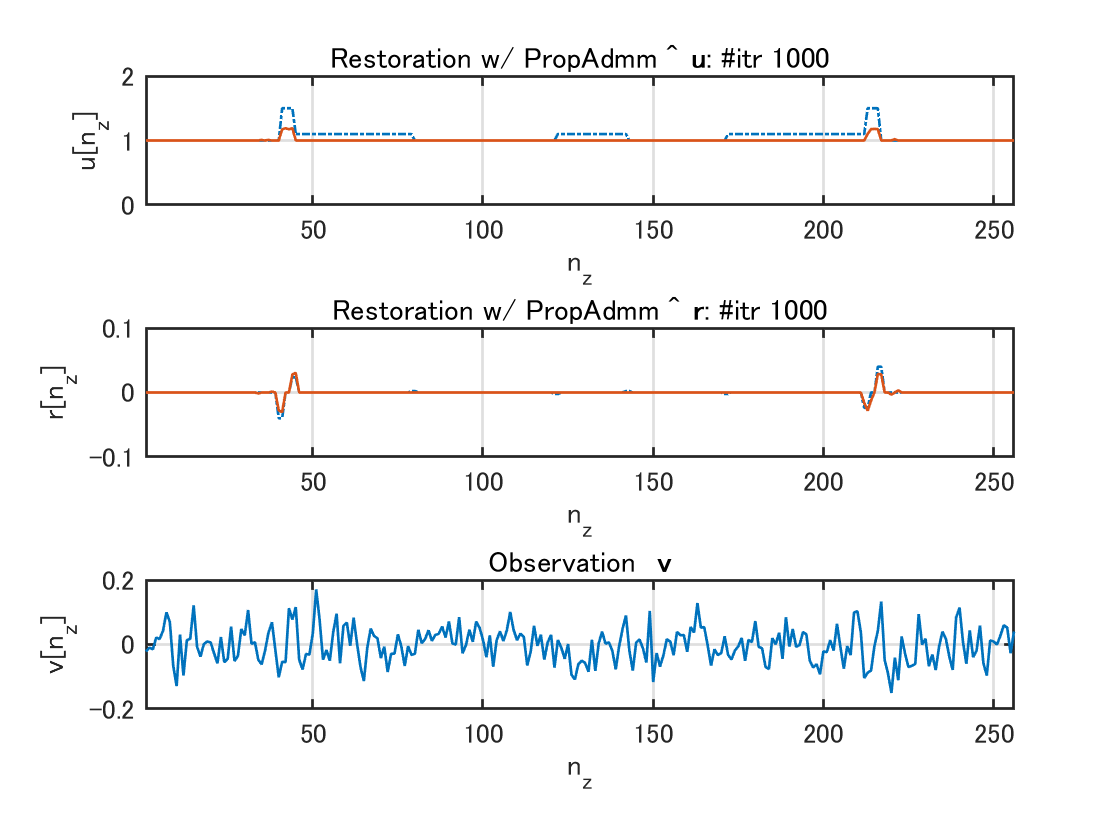

invpQ_ = @(x) invpQ(x,diagR_,rho_admm,{analyzer, synthesizer},nSamples);
mse_r_propadmm = zeros(nIters_admm,1);
proctime_propadmm_invQ = 0;
proctime_propadmm_other = 0;
for itr=1:nIters_admm
    tic
    % Step 1
    %t_ = y_ + rho_admm*(adjpG1(z1p-d1p) + adjpG2(z2p-d2p));
    z11p = z1p(1:nCoefs);
    d11p = d1p(1:nCoefs);
    z12p = z1p(nCoefs+1:end);
    d12p = d1p(nCoefs+1:end);
    adjrev = adjpG11(z11p-d11p) ...
        + reshape(analyzer(adjpG12_wo_ana(z12p-d12p)+adjpG2_wo_ana(z2p-d2p)),[],1);
    t_ = y_ + rho_admm*(adjrev);
    %   Time measurement
    proctime_propadmm_other = proctime_propadmm_other + toc;
    tic
    sc = invpQ_(t_);
    %   Time measurement
    proctime_propadmm_invQ = proctime_propadmm_invQ + toc;
    %
    tic
    % Step 2
    %procG1sc = procG1(sc);
    %procG2sc = procG2(sc);
    uc = synthesizer(sc);
    procG1sc = [ procG11(sc); procG12_wo_syn(uc) ];
    procG2sc = procG2_wo_syn(uc);   
    z1c = softthresh(procG1sc + d1p, lambda_prop_admm/rho_admm); 
    z2c = metricproj(procG2sc + d2p, ri_lb, ri_ub);
    % Step 3
    d1c = d1p + procG1sc - z1c;
    d2c = d2p + procG2sc - z2c;
    % Update 
    z1p = z1c;
    z2p = z2c;
    d1p = d1c;
    d2p = d2c;
    %   Time measurement
    proctime_propadmm_other = proctime_propadmm_other + toc;

    % Process or monitoring
    uc = synthesizer(sc);
    rc = phi1d(uc,'linear',[ri_lb ri_ub]);
    hrc.YData = rc;
    rtitle.String = ['Restoration w/ PropAdmm \^{\bf r}: #itr ' num2str(itr)];
    huc.YData = uc;
    utitle.String = ['Restoration w/ PropAdmm \^{\bf u}: #itr ' num2str(itr)];
    drawnow
    %
    mse_r_propadmm(itr) = mymse(r,rc);
end

disp(['MSE (Prop. ADMM): ' num2str(mymse(r,rc))]);

MSE (Prop. ADMM): 3.4065e-06


hr_propadmm = rc;
hu_propadmm = uc;

## Reference restoration w/ 1D TV

    $\hat{\mathbf{r}}=\arg \min _{\mathbf{r} \in[-1, 1]^{N}} \frac{1}{2}\|\mathbf{P} \mathbf{r}-\mathbf{v}\|_{2}^{2}+\eta\left\| \mathfrak{D}_\mathrm{z}\mathbf{r}\right\|_\mathrm{1}$,

which is equivalently represented by 

    $\hat{\mathbf{r}}=\arg \min _{\mathbf{r} \in\mathbb{R}^{N}} \frac{1}{2}\|\mathbf{P} \mathbf{r}-\mathbf{v}\|_{2}^{2}+\iota_{[-1,1]^N}(\mathbf{r})+\eta\left\| \mathfrak{D}_\mathrm{z}\mathbf{r}\right\|_\mathrm{1}$,

where  $\mathfrak{D}_\mathrm{z}$  is the matrix representation of the first-order difference filter that subtracts neighboring pixels, i.e., $1-z^{-1}$.

Reference: 

- M. Shamouilian and I. Selesnick, "Total Variation Denoising for Optical Coherence Tomography," 2019 IEEE Signal Processing in Medicine and Biology Symposium (SPMB), 2019, pp. 1-5, doi: 10.1109/SPMB47826.2019.9037832.

NOTE: This approach corresponds the proposed model when  $\mathbf{\Phi}_1$, $\mathbf{D}$ are set to the identity, $\mathbf{\Delta}_z$ is replaced by $\nabla$, $[a,b]=[-1,1]$ and $\lambda=0$.

% Impluse response of the first-order difference filter
fdf = [1 -1];
% Difference process
diffproc = @(x) circshift(cconv(fdf,x,nSamples),-floor(length(fdf)/2));
diffadjp = @(x) circshift(cconv(fdf(end:-1:1),x,nSamples),mod(length(fdf)-1,2)-floor(length(fdf)/2)); 
% Check if <Px,y> = <x,P.'y> (is adjoint?)
isinadjrel(diffproc,diffadjp,nSamples)

Initialization: $\mathbf{r}^{(0)}, \mathbf{y}^{(0)}, n \leftarrow 0$

- 
$$\mathbf{r}^{(n+1)} \leftarrow \mathcal{P}_{[-1,1]^{N}}\left(\mathbf{r}^{(n)}-\gamma_{1}\left( \mathbf{P}^{T}(\mathbf{P} \mathbf{r}^{(n)}-\mathbf{v})+\mathfrak{D}_\mathrm{z}^{T} \mathbf{y}^{(n)}\right)\right)$$


- 
$$\mathbf{y}^{(n+1)} \leftarrow \mathrm{prox}_{\gamma_{2}(\eta\|\cdot\|_{1})^{*}}\left(\mathbf{y}^{(n)}+\gamma_{2} \mathfrak{D}_\mathrm{z}\left(2 \mathbf{r}^{(n+1)}-\mathbf{r}^{(n)}\right)\right)$$


where

- 
$$\mathrm{prox}_{\gamma(\eta\|\cdot\|_{1})^{*}}(\mathbf{x})=\mathbf{x}-\gamma \mathrm{prox}_{\gamma^{-1}\eta\|\cdot\|_{1}}\left(\gamma^{-1} \mathbf{x}\right)$$


- 
$$\gamma \mathrm{prox}_{\gamma^{-1}\eta\|\cdot\|_{1}}\left(\gamma^{-1} \mathbf{x}\right)=  \mathrm{sign}(\mathbf{x})\odot\max \left\{\mathrm{abs}(\mathbf{x})-\eta\mathbf{1}, 0\right\}$$
 

- 
$$\gamma_{1}^{-1}-\gamma_{2}\left(\sigma_{\max }(\mathfrak{D}_\mathrm{z})\right)^{2} \geq 2 ^{-1}\left(\sigma_{\max }(\mathbf{P})\right)^{2}$$



$$\mathrm{prox}_{\tau\|\cdot\|_{1}}\left(\mathbf{x}\right)=  \mathrm{sign}(\mathbf{x})\odot\max \left\{\mathrm{abs}(\mathbf{x})-\tau\mathbf{1}, 0\right\}$$


Initialization

yp = zeros(size(v),'like',v);
rp = v;

Settings for stepsize $\gamma_2$

mu_tv = max(abs(fft(irp,nSamples)).^2,[],'all'); % (σmax(P))^2
tau2_tv = max(abs(fft(fdf,nSamples)).^2,[],'all');  % (σmax(L))^2
gamma1_tv = 2/(1.05*mu_tv);
gamma2_tv = 1/(1.05*tau2_tv)*(1/gamma1_tv-mu_tv/2);
assert((1/gamma1_tv - gamma2_tv*tau2_tv) > mu_tv/2,...
    ['Step size condition is violated. γ1 must be less than ' num2str(2/mu_tv)])
strbuf = "";
strbuf = strbuf.append("mu: "+ num2str(mu_tv) + newline);
strbuf = strbuf.append("tau2: " +  num2str(tau2_tv) + newline);
strbuf = strbuf.append("gamma1: " +  num2str(gamma1_tv) + newline);
strbuf = strbuf.append("gamma2: " +  num2str(gamma2_tv) + newline);
disp(strbuf)

mu: 100.0131
tau2: 4
gamma1: 0.019045
gamma2: 0.59532



Graph plot

hfig = figure;
subplot(3,1,1)
plot(u,'-.') % Original refractive index distribution
title('Latent refractive index {\bf u}');
xlabel('n_z')
ylabel('u[n_z]')
axis([1 nSamples 0 2])
%
subplot(3,1,2)
plot(r,'-.') % Original reflectance distribution
rtitle = title(['Restoration w/ Ref1dtv \^{\bf r}: #itr ' num2str(0)]);
xlabel('n_z')
ylabel('r[n_z]')
axis([1 nSamples -0.1 0.1])
hold on
hrc = plot(rp); % Restored reflectance distribution
hold off
%
subplot(3,1,3)
plot(v) % Observation
title('Observation {\bf v}')
xlabel('n_z')
ylabel('v[m_z]')
axis([1 nSamples -0.2 0.2])
%
viewhandle_(hfig)
drawnow

Primal-dual splitting method for 1D TV

- 
$$\mathbf{r}^{(n+1)} \leftarrow \mathcal{P}_{[-1,1]^{N}}\left(\mathbf{r}^{(n)}-\gamma_{1}\left(\mathbf{P}^{T}(\mathbf{P} \mathbf{r}^{(n)}-\mathbf{v})+\mathbf{\nabla}^{T} \mathbf{y}^{(n)}\right)\right)$$


- 
$$\mathbf{y}^{(n)}\leftarrow \mathbf{y}^{(n)}+\gamma_{2} \mathbf{\nabla}\left(2 \mathbf{r}^{(n+1)}-\mathbf{r}^{(n)}\right)$$


- 
$$\mathbf{y}^{(n+1)} \leftarrow \mathbf{y}^{(n)}-\mathrm{sign}(\mathbf{y}^{(n)})\odot\max \left\{\mathrm{abs}(\mathbf{y}^{(n)})-\eta\mathbf{1}, 0\right\}$$


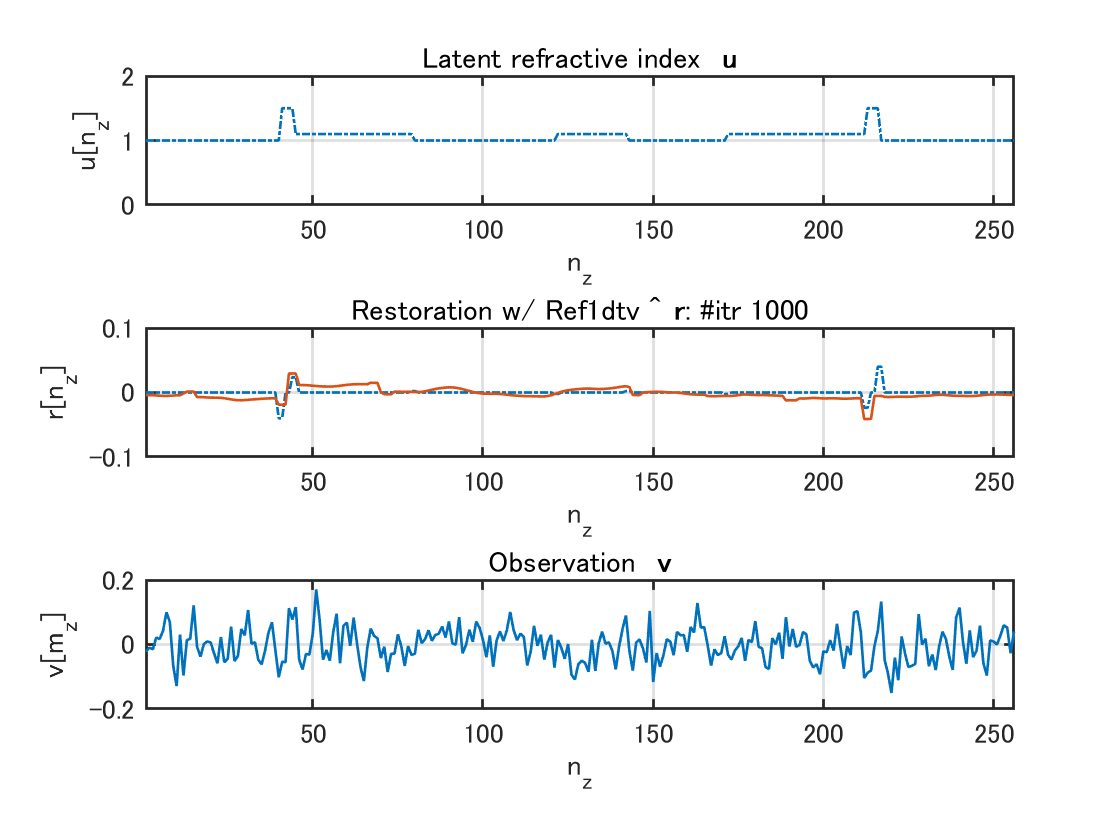

rmax = 1;
rmin = -1;
mse_r_ref1dtv = zeros(nIters_1dtv,1);
proctime_ref1dtv = 0;
for itr=1:nIters_1dtv
    tic
    % Primal step
    rg = measureadjp(measureproc(rp)-v);
    rc = metricproj(rp-gamma1_tv*(rg + diffadjp(yp)),rmin,rmax);
    % Dual step
    yt = yp + gamma2_tv*diffproc(2*rc - rp);
    yc = yt - softthresh(yt,eta_1dtv);
    % Update
    rp = rc;
    yp = yc;
    % Time measurement
    proctime_ref1dtv = proctime_ref1dtv + toc;

    % Process for monitoring
    hrc.YData = rc;
    rtitle.String = ['Restoration w/ Ref1dtv \^{\bf r}: #itr ' num2str(itr)];
    drawnow
    %
    mse_r_ref1dtv(itr) = mymse(r,rc);
end

disp(['MSE (Ref. 1DTV): ' num2str(mymse(r,rc))])

MSE (Ref. 1DTV): 7.7063e-05


hr_refpds = rc;

## Materials

### Comparison of convergence characteristics

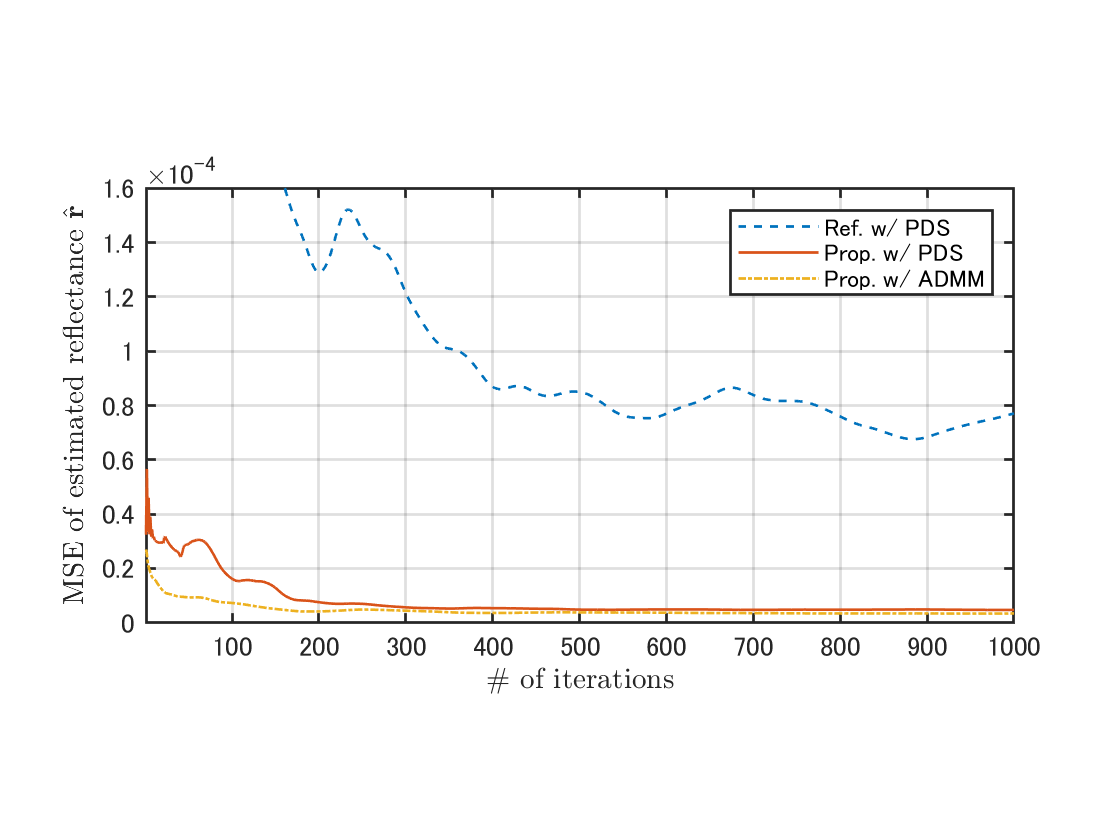

hfig = figure;
hplt = plot(...
        1:nIters_1dtv, mse_r_ref1dtv,'--',...
    1:nIters_pds,  mse_r_proppds,...
    1:nIters_admm, mse_r_propadmm,'-.',....
    'LineWidth',1);
xlabel('\# of iterations','Interpreter','latex')
ylabel('MSE of estimated reflectance $\hat{\mathbf{r}}$','Interpreter','latex')
legend('Ref. w/ PDS','Prop. w/ PDS','Prop. w/ ADMM')
grid on
%title('Convergence characteristics')
ax = hplt.Parent;
ax.DataAspectRatio = [1000 2*1.6e-4 1];
%daspect([1000 2*1.6e-4 1])

axis([1 nIters 0 1.6e-4])
hax = hplt.Parent;
hax.FontSize = 10;
hax.LineWidth = 1;

%print(hfig,'./results/figonvergence','-dpng')
exportgraphics(hfig,'./results/fig6arev.png','Resolution',300) 

close(hfig)

### Estimation results 

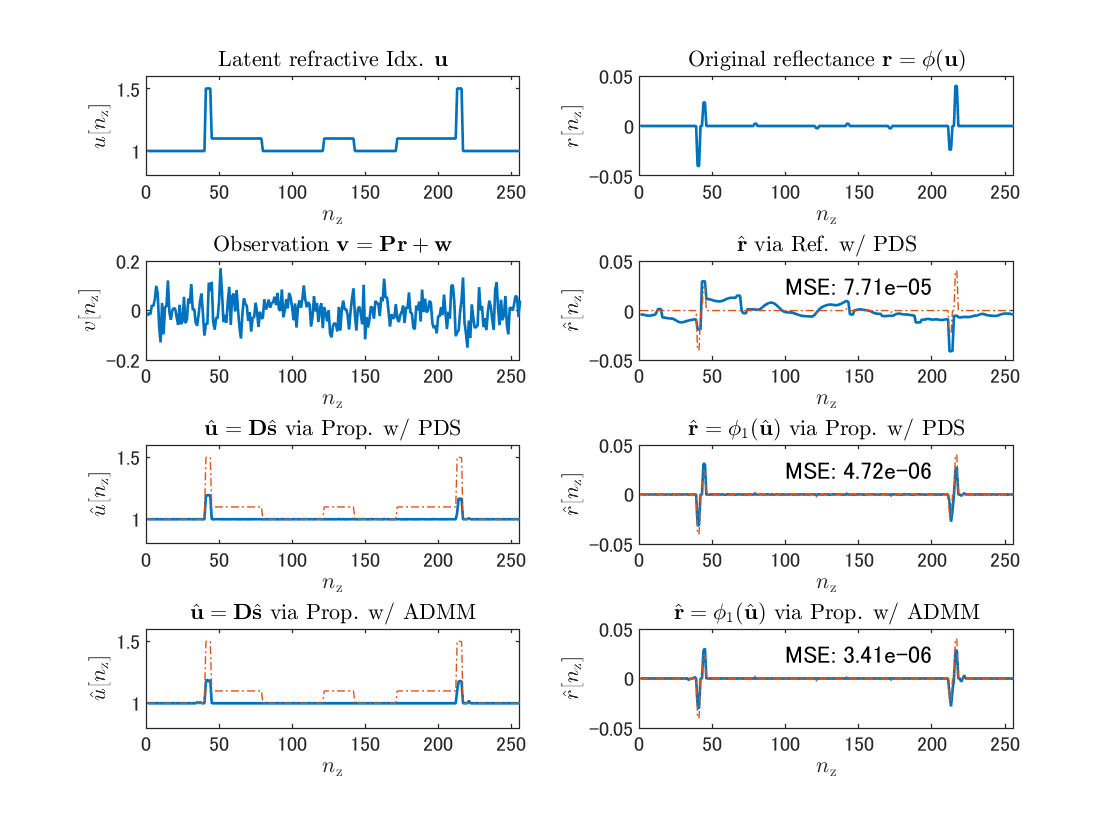

figure
umin = 0.8;
umax = 1.6;
vmin = -0.2;
vmax = 0.2;
rmin = -5e-2;
rmax = 5e-2;
% u 
subplot(4,2,1)
plot(u,'LineWidth',1)
axis([0 256 umin umax])
title('Latent refractive Idx. $\mathbf{u}$','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$u[n_\mathrm{z}]$','Interpreter','latex')
%grid on
hax = gca;
exportgraphics(hax,'./results/fig5arev.png','Resolution',300) 

% r
subplot(4,2,2)
plot(r,'LineWidth',1)
axis([0 256 rmin rmax])
title('Original reflectance $\mathbf{r}=\mathbf{\phi}(\mathbf{u})$','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$r[n_\mathrm{z}]$','Interpreter','latex')
%grid on
hax = gca;
exportgraphics(hax,'./results/fig5brev.png','Resolution',300) 

% v 
subplot(4,2,3)
plot(v,'LineWidth',1)
axis([0 256 vmin vmax])
title('Observation $\mathbf{v}=\mathbf{Pr}+\mathbf{w}$','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$v[n_\mathrm{z}]$','Interpreter','latex')
%grid on
hax = gca;
exportgraphics(hax,'./results/fig5crev.png','Resolution',300) 

% hr_refpds
subplot(4,2,4)
plot(hr_refpds,'LineWidth',1)
axis([0 256 rmin rmax])
title('$\hat{\mathbf{r}}$ via Ref. w/ PDS','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$\hat{r}[n_\mathrm{z}]$','Interpreter','latex')
text(100,25e-3,"MSE: "+num2str(mymse(r,hr_refpds),'%0.2e'))
%grid on
hold on
plot(r,'-.')
hold off
hax = gca;
exportgraphics(hax,'./results/fig5drev.png','Resolution',300) 

% hu_proppds 
subplot(4,2,5)
plot(hu_proppds,'LineWidth',1)
axis([0 256 umin umax])
title('$\hat{\mathbf{u}}=\mathbf{D}\hat{\mathbf{s}}$ via Prop. w/ PDS','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$\hat{u}[n_\mathrm{z}]$','Interpreter','latex')
%grid on
hold on
plot(u,'-.')
hold off
hax = gca;
exportgraphics(hax,'./results/fig5erev.png','Resolution',300) 

% hr_proppds
subplot(4,2,6)
plot(hr_proppds,'LineWidth',1)
axis([0 256 rmin rmax])
title('$\hat{\mathbf{r}}=\mathbf{\phi}_1(\hat{\mathbf{u}})$ via Prop. w/ PDS','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$\hat{r}[n_\mathrm{z}]$','Interpreter','latex')
text(100,25e-3,"MSE: "+num2str(mymse(r,hr_proppds),'%0.2e'))
%grid on
hold on
plot(r,'-.')
hold off
hax = gca;
exportgraphics(hax,'./results/fig5frev.png','Resolution',300) 

% hu_propadmm 
subplot(4,2,7)
plot(hu_propadmm,'LineWidth',1)
axis([0 256 umin umax])
title('$\hat{\mathbf{u}}=\mathbf{D}\hat{\mathbf{s}}$ via Prop. w/ ADMM','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$\hat{u}[n_\mathrm{z}]$','Interpreter','latex')
%grid on
hold on
plot(u,'-.')
hold off
hax = gca;
exportgraphics(hax,'./results/fig5grev.png','Resolution',300) 

% hr_propadmm
subplot(4,2,8)
plot(hr_propadmm,'LineWidth',1)
axis([0 256 rmin rmax])
title('$\hat{\mathbf{r}}=\mathbf{\phi}_1(\hat{\mathbf{u}})$ via Prop. w/ ADMM','Interpreter','latex')
xlabel('$n_\mathrm{z}$','Interpreter','latex')
ylabel('$\hat{r}[n_\mathrm{z}]$','Interpreter','latex')
text(100,25e-3,"MSE: "+num2str(mymse(r,hr_propadmm),'%0.2e'))
%grid on
hold on
plot(r,'-.')
hold off
hax = gca;
exportgraphics(hax,'./results/fig5hrev.png','Resolution',300) 

### Processing time

ave_proctime_proppds = proctime_proppds/nIters_pds;
ave_proctime_propadmm_other = proctime_propadmm_other/nIters_admm;
ave_proctime_propadmm_invQ = proctime_propadmm_invQ/nIters_admm;
ave_proctime_ref1dtv = proctime_ref1dtv/nIters_1dtv;
proctimetbl = table(...
    ["Ref. w/ PDS";"Proc. w/ PDS";"Proc. w/ ADMM"],...
    [ave_proctime_ref1dtv;ave_proctime_proppds;ave_proctime_propadmm_other],[0;0;ave_proctime_propadmm_invQ],...
    'VariableNames',["Method","Time1","Time2"]);
proctimetbl.Method = categorical(proctimetbl.Method)

proctimetbl = 3×3 table
       Method          Time1         Time2  
    _____________    __________    _________

    Ref. w/ PDS      0.00039611            0
    Proc. w/ PDS       0.004805            0
    Proc. w/ ADMM      0.004026    0.0034597


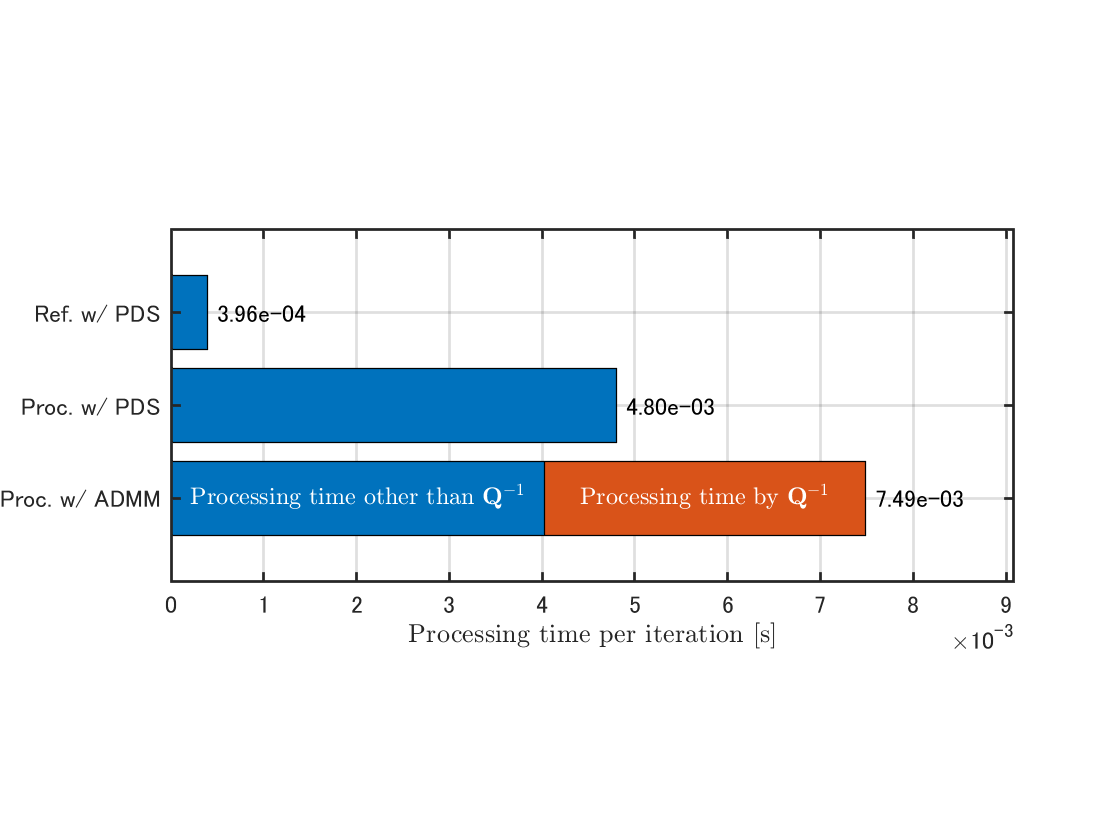

hfig = figure;
hb = barh(proctimetbl.Method,[proctimetbl.Time1,proctimetbl.Time2],'stacked');
xlabel("Processing time per iteration [s]","Interpreter","latex")
xtips1 = hb(1).YEndPoints;
xtips2 = hb(2).YEndPoints;
ytips2 = hb(2).XEndPoints;
labels2 = num2str(proctimetbl.Time1(:)+proctimetbl.Time2(:),'%0.2e');
text(xtips1(3)/2,ytips2(3),'Processing time other than $\mathbf{Q}^{-1}$','HorizontalAlignment','center','VerticalAlignment', 'middle','Color','white','Interpreter','latex')
text((xtips1(3)+xtips2(3))/2,ytips2(3),'Processing time by $\mathbf{Q}^{-1}$','HorizontalAlignment','center','VerticalAlignment', 'middle','Color','white','Interpreter','latex')
text(xtips2+1e-4,ytips2,labels2,'VerticalAlignment', 'middle')
ax =hb.Parent;
ax.DataAspectRatio = [1e-3 1 1];
%daspect([1e-3 1 1])
hax = hb.Parent;
hax.XLim = [0 max(hb(2).YEndPoints)+1.6e-3];
hax.LineWidth = 1;
grid on
exportgraphics(hfig,'./results/fig6brev.png','Resolution',300) 

close(hfig)

### Information in LaTeX format

capstr = "";
capstr = capstr.append("\# of tree levels is " + num2str(nLevels) + newline);
capstr = capstr.append("$\sigma_\mathrm{w} = " + num2str(sigmaw) + "$"+ newline);
fid = fopen("./results/caption.tex","w");
fwrite(fid,capstr);
fclose(fid);


## Functions

### Soft thresholding

    
$$\mathcal{T}(\mathbf{x},\tau)=\mathrm{sign}(\mathbf{x}) \odot\max\left\{\mathrm{abs}(\mathbf{x})-\tau\mathbf{1},\mathbf{0}\right\}$$


function y = softthresh(x,t)
    y = sign(x).*max(abs(x)-t,0);
end

### Function to convert refractive index to reflection

    
$$\phi(\mathbf{u})=\mathrm{abs}\left(\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}\right) \odot\left(-\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}\right) \oslash\left(\mathbf{A}_{\mathrm{z}} \mathbf{u}\right)^{\circ 2}$$


    
$$\phi_1(\mathbf{u})= -\frac{2|b-a|}{(b+a)^2}\mathbf{\Delta}_{\mathrm{z}} \mathbf{u}$$


function y = phi1d(u,mode,ribound)
    dz = [1 0 -1];
    az = [1 0  1];
    dzu = circshift(cconv(dz,u,length(u)),-1);
    azu = circshift(cconv(az,u,length(u)),-1);
    if nargin < 3
        ribound = [1.0 1.5];
    end
    if strcmp(mode,'reflection')
        y = abs(dzu).*(-dzu)./(azu.^2);
    elseif strcmp(mode,'linear')
        b = ribound(2);
        a = ribound(1);
        y = -beta1(a,b)*dzu;
    else
        error('Not supported')
    end
end

function b = beta1(a,b)
    b = 2*abs(b-a)/(b+a)^2;
end

## Distance projection

function y = metricproj(x,ymin,ymax)
    y= min(max(x,ymin),ymax);
end

### Function to check the adjoint relationship

function isinadjrel(fwdp,adjp,nSamples1,nSamples2)
    if nargin < 4
        nSamples2 = nSamples1;
    end
    x1 = randn(nSamples1,1);
    y1 = fwdp(x1);
    y2 = randn(nSamples2,1);
    x2 = adjp(y2);
    err = abs(x1(:).'*x2(:)-y1(:).'*y2(:));
    assert(err<1e-9,'Adjoint relation is not met. (abs err: %f)',err)
end

### Dictionary

% Undecimated Haar decomposition
function y = udhaardec(x,nLevels)
    swc = swtscale(nLevels)*swt(x,nLevels,'haar');
    y = swc(:);
end

% Undecimated Haar reconstruction
function x = udhaarrec(y,nLevels)
    swc = swtscale(nLevels)\reshape(y,nLevels+1,[]);
    x = iswt(swc,'haar');
end

% Scaling factor for Parseval tight property 
function s = swtscale(nLevels)
    s = diag([2.^(-(1:nLevels)/2) 2^(-nLevels/2)]);
end

### **Support functions for ADMM **

function y = procQ(x,diagH,rho,dictionaries,nSamples)
    analyzer = dictionaries{1};
    synthesizer = dictionaries{2};
    % Definition of process by matrix Q
    s_ = synthesizer(x);
    y = rho*x(:) + reshape(analyzer(ifft(diagH.*reshape(fft(s_,nSamples),[],1),nSamples)+rho*s_(:)),[],1);
end

function y = invpQ(x,diagR,rho,dictionaries,nSamples)
    analyzer = dictionaries{1};
    synthesizer = dictionaries{2};
    % Definition of process by matrix inv(Q)
    s_ = synthesizer(x);
    y = x(:)/rho - (1/rho)^2*reshape(analyzer((1/4)*ifft(diagR.*reshape(fft(s_,nSamples),[],1),nSamples)+(rho/2)*s_(:)),[],1);
end

### Function for handling figures

function viewhandle_(hfig)
axes = hfig.Children;
nAxes = length(axes);
for iAxis = 1:nAxes
    haxis_ = axes(iAxis);
    haxis_.LineWidth = 1;
    haxis_.FontSize = 10;
    haxis_.XGrid = 'on';
    haxis_.YGrid = 'on';
    hcontents_ = haxis_.Children;
    nContents = length(hcontents_);
    for iContent = 1:nContents
        hcontent_ = hcontents_(iContent);
        hcontent_.LineWidth = 1;
    end
end
end